% imshow("map1.png")
% hold on
% [xi,yi] = getpts();
% Path = [xi yi];
% 初始化矩阵
clear
hold off
plot([],[]);
points = zeros(100, 2);

% 设置初始点
points(1, :) = [0, 0];
angle = 0;
% 生成剩余的点
for i = 2:100
    % 确保点与点之间的距离为1
    angle =angle + rand(1,1)  * pi/3 - pi / 6; % 随机角度
    dx = 0.2 * cos(angle); % x方向的增量
    dy = 0.2 * sin(angle); % y方向的增量
    
    
    points(i, 1) = points(i-1, 1) + dx; % 更新x坐标
    points(i, 2) = points(i-1, 2) + dy; % 更新y坐标
end
Path = points;
increase = 1;
Path = Path*increase;
M_5 = [1 11 11 1 0;
    -4 -12 12 4 0;
    6 -6 -6 6 0;
    -4 12 -12 4 0;
    1 -4 6 -4 1]./24;
M_4 = [1 / 6, 4 / 6, 1 / 6, 0;
    -3 / 6, 0, 3 / 6, 0;
    3 / 6, -6 / 6, 3 / 6, 0;
    -1 / 6, 3 / 6, -3 / 6, 1 / 6 ];
M_k = M_4;
A = M_k(1,:);
hold on
tmpPath = Path;
h = size(tmpPath,1)/(size(tmpPath,1)-3); 
H = zeros(size(tmpPath,1),1);
H(2) = h/6;
H(3) = 2*h/3;
H(4) = 3*h/2;
for i= 5:size(tmpPath,1)-2
    H(i) =H(i-1) + h; 
end
H(size(tmpPath,1)-2) =H(size(tmpPath,1)-3) + 5*h/6; 
H(size(tmpPath,1)-1) =H(size(tmpPath,1)-2) + 1*h/2; 
H(size(tmpPath,1)) =H(size(tmpPath,1)-1) + 1*h/6; 
for i = 2 : size(tmpPath,1)
    tmpPath(i,:) = (Path(i,:) - Path(i-1,:)).*(H(i) - i + 1) + Path(i,:);
end
tmpPath = zeros(size(Path,1) + 4,size(Path,2));
vec =Path(2,:) - Path(1,:); 
tmpPath(1:4,:) = [Path(1,:);Path(1,:)+vec*0.04984;Path(1,:)+vec*0.36338;Path(1,:)+vec*1.04984] ;
tmpPath(5:size(Path,1),:) = Path(3:size(Path,1)-2,:);
vec =Path(end,:) - Path(end-1,:); 
tmpPath(size(Path,1)+1:size(Path,1)+4,:) = [Path(end,:)-vec*1.04984;Path(end,:)-vec*0.36338;Path(end,:)-vec*0.04984;Path(end,:)] ;
% Path = tmpPath;
for i = 2:size(Path,1)
    B = A(end,:);
    A = [A,zeros(i - 1,1)];
    A = [A;0,B];
end
A = [A;-A];
A = [A;zeros(1,size(Path,1) - 1),M_k(2,:)];
A = [A;M_k(2,:),zeros(1,size(Path,1) - 1)];
A = [A;zeros(1,size(Path,1)-1),M_k(3,:)];
A = [A;M_k(3,:),zeros(1,size(Path,1) - 1)];
A(:,end) = [];
Aeq = A(end-3:end,:);
A(end-3:end,:) = [];

loose = Path;
loose = loose * 0 + 0.15;
loose(1,:) = [0,0];
loose(end,:) = [0,0];
b = [Path+loose;-Path+loose;];
beq = [0,0;0.01 0.01;0 0;0 0]

beq =          0         0
    0.0100    0.0100
         0         0
         0         0



H =zeros(4);
H_0 = H;
for t = 0:100
    H_0 =H_0 + (M_k' * [0,0,2,6*t/100]'*[0,0,2,6*t/100] * M_k);
end
H = H_0;
for i = 2:size(Path,1) - 1
    H = [H,zeros(size(H,1),1);
           zeros(1,size(H,1)),0]    + [zeros(size(H,1) - size(H_0,1) +1),zeros(size(H,1) - size(H_0,1) +1,size(H_0,2));
         zeros(size(H_0,1),size(H,1) - size(H_0,1) +1),H_0];
end

BsplineControlPoint = zeros(size(Path,1)+2,2); 
options = optimoptions('quadprog', 'MaxIterations', 100);


[BsplineControlPoint(:,1),fval] = quadprog(H,[],A,b(:,1),Aeq,beq(:,1),[],[],[],options);


找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


BsplineControlPoint(:,2) = quadprog(H,[],A,b(:,2),Aeq,beq(:,2),[],[],[],options);


找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>




TimeLine = rand(1,size(Path,1) + 5);
TimeLine(1) = -2;
for k = 2: (size(Path,1)+5)
    TimeLine(k) = 1 + TimeLine(k - 1);
end
TimeLine= TimeLine*0.01;


OptimizedControlPos = BsplineControlPoint;
 % for i = 1:10
 %    for p = 2:size(Path,1) - 2
 %         Path(p,:) =Path(p,:) + (Path(p - 1,:) - Path(p,:)) * 0.2  + (Path(p + 1,:) - Path(p,:)) * 0.2 ;
 %     end
 %     BsplineControlPoint = OptimizedControlPos;
 % end

hold off


[x1, y1] = GetTrajectoryForNUB( OptimizedControlPos,TimeLine);
ts = linspace(0,TimeLine(end-3) ,size(x1,2));
diffx = diff(x1) ./ diff(ts);
diffy = diff(y1) ./ diff(ts);
diffv = sqrt(diffx.*diffx + diffy.*diffy);
ts = linspace(0,TimeLine(end-3) ,size(x1,2)-1);
scatter(ts,diffv,'b');
hold on
ts = linspace(0,TimeLine(end-3) ,size(x1,2)-1);
diffa = 2*diff(diffv);
ts(end)= [];
scatter(ts,diffa,'g');
hold on
sum(diffa)

ans = -2.7877

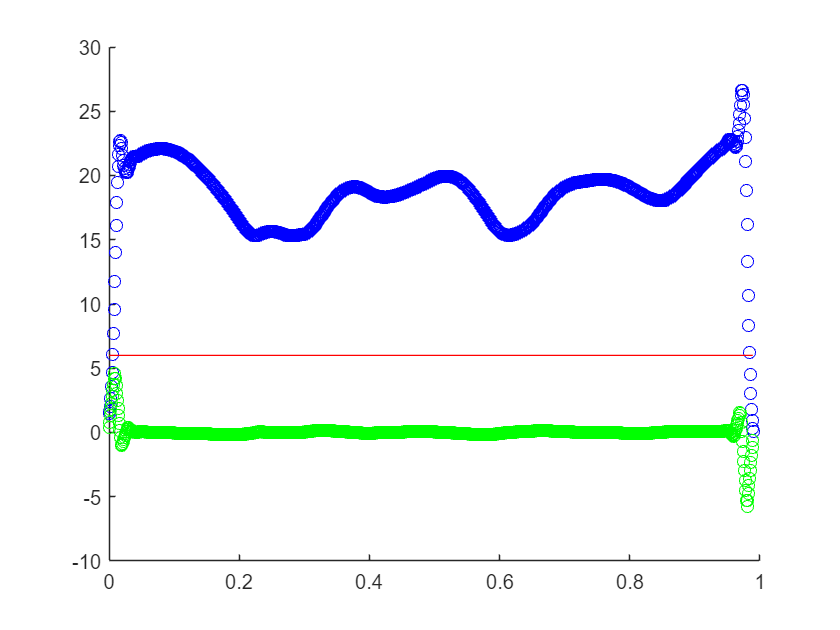

plot(ts,ones(size(ts,1),size(ts,2))*6,'r')
hold off

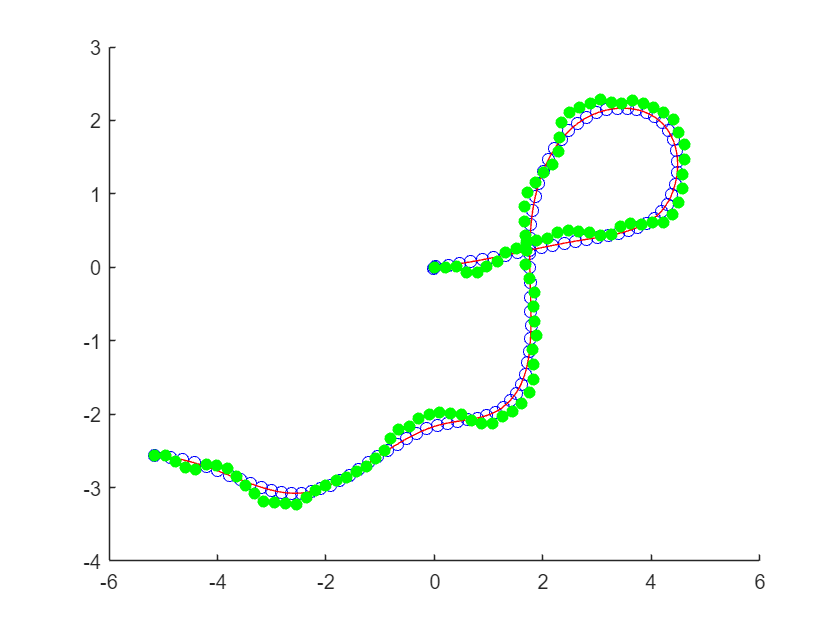




scatter(Path(:,1),Path(:,2),"filled",'r')
hold on
scatter(BsplineControlPoint(:,1),BsplineControlPoint(:,2),'blue');
hold on
TimeLine = ReallocTimeLine(OptimizedControlPos,TimeLine);
[x1, y1] = GetTrajectoryForNUB( OptimizedControlPos,TimeLine);
plot(x1,y1,'r')
hold on
scatter(Path(:,1),Path(:,2),"filled",'g')

hold off





[x2, y2] =GetVelocityForNUB( OptimizedControlPos,TimeLine);
ts = linspace(0,TimeLine(end-3) ,size(x1,2));
diffx = diff(x1) ./ diff(ts);
diffy = diff(y1) ./ diff(ts);
diffv = sqrt(diffx.*diffx + diffy.*diffy)

diffv =     0.1217    0.1217    0.1235    0.1271    0.1327    0.1404    0.1503    0.1625    0.1771    0.1942    0.2137    0.2357    0.2601    0.2869    0.3161    0.3477    0.3817    0.4180    0.4566    0.4976    0.5408    0.5864    0.6342    0.6844    0.7368    0.7915    0.8484    0.9076    0.9676    1.0255    1.0810    1.1342    1.1849    1.2332    1.2792    1.3227    1.3639    1.4026    1.4389    1.4729    1.5044    1.5335    1.5603    1.5846    1.6065    1.6260    1.6431    1.6579    1.6702    1.6801


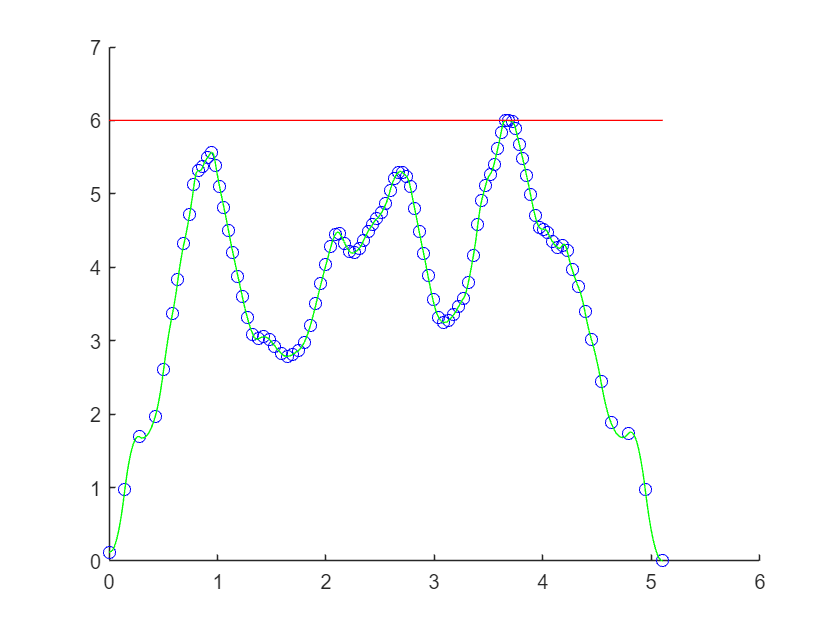

ts = linspace(0,TimeLine(end-3) ,size(x1,2)-1);

for p = round(TimeLine ./ ((ts(2) - ts(1))))
    if p < 0 || p >= 999 
        continue;
    end
    scatter(p*(ts(2) - ts(1)),diffv(p+1),'blue');
    hold on
end
plot(ts,sqrt(x2.*x2 + y2.*y2),'g');
    hold on
plot(ts,ones(size(ts,1),size(ts,2))*6,'r')

hold off